
folderName = "/Users/gershikoral/Desktop/labproject/mono";

normalizeMethod = "range";
rangeValues = [-1,1];
standardizationMethod = "zscore";

folder = fullfile(matlabroot,'toolbox','audio','samples');
ads = audioDatastore(folderName,"IncludeSubfolders",true, "LabelSource","foldernames");

[filenames,~] = cellfun(@(x)fileparts(x),ads.Files,'UniformOutput',false);
filenames = (string(filenames));
wordSplit = split(filenames,"/");
segmentation = wordSplit(:,end);


ads.Labels = categorical(segmentation);

clear folderName filenames wordSplit segmentation

trainRatio = 0.6;
validationRatio = 0.25;
testRatio = 1-trainRatio-validationRatio;
shuf= shuffle(ads)

shuf =   audioDatastore with properties:

                       Files: {
                              ' .../mono/False/Discussion   Psychological impact of COVID-19_07.wav';
                              ' .../Desktop/labproject/mono/True/COVID19inSAreadinessofschools_7.wav';
                              ' .../mono/False/Discussion   Psychological impact of COVID-19_08.wav'
                               ... and 311 more
                              }
                     Folders: {
                              '/Users/gershikoral/Desktop/labproject/mono'
                              }
                      Labels: [False; True; False ... and 311 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


[train,validation,test] = splitEachLabel(shuf,trainRatio,validationRatio,testRatio,'randomized');

% tallTrain      = tall(train);
% tallValidation = tall(validation);
% tallTest = tall(test);

tallTrain      = readall(train);
tallValidation = readall(validation);
tallTest = readall(test);



clear trainRatio validationRatio testRatio 

%Matlab feature extraction occurs here
[~,adsInfo] = read(ads);
fs = adsInfo.SampleRate;

%Produces a frame size of 30ms
%https://www.mathworks.com/help/audio/ug/sequential-feature-selection-for-audio-features.html#mw_rtc_SequentialFeatureSelectionForAudioFeaturesExample_FDEE1A23
%Code above specifies that this sets the overlap and window size as
%required
%t_n = n*T ( the location of the sample = time step * Period)
win = hamming(round(0.03*fs),"periodic"); 
%Produces an overlap length of 15ms --> 50% of the original
overlapLength = round(0.015*fs);


afe = audioFeatureExtractor( ...
    'Window',       win, ...
    'OverlapLength',overlapLength, ...
    'SampleRate',   fs, ...
    "pitch",true,...
    "harmonicRatio", true);


%Extract features
trainFeatures       = cellfun(@(x)extract(afe,x),tallTrain,"UniformOutput",false);
validationFeatures =cellfun(@(x)extract(afe,x),tallValidation,"UniformOutput",false);
testFeatures =cellfun(@(x)extract(afe,x),tallTest,"UniformOutput",false);


%Standardization
trainFeaturesStandardise        = cellfun(@(x)normalize(x, standardizationMethod),trainFeatures ,"UniformOutput",false);
%Normalise Features
trainFeaturesNormed       = cellfun(@(x)normalize(x,normalizeMethod,rangeValues),trainFeaturesStandardise  ,"UniformOutput",false);


validationFeaturesStandardise = cellfun(@(x)normalize(x,standardizationMethod),validationFeatures ,"UniformOutput",false);
testFeaturesStandardize= cellfun(@(x)normalize(x,standardizationMethod),testFeatures ,"UniformOutput",false);


validationFeaturesNormed= cellfun(@(x)normalize(x,normalizeMethod,rangeValues),validationFeaturesStandardise ,"UniformOutput",false);
testFeaturesNormed= cellfun(@(x)normalize(x,normalizeMethod,rangeValues),testFeaturesStandardize ,"UniformOutput",false);
YTrain = train.Labels;
YValidation = validation.Labels;
YTest = test.Labels;

XTrainData = cellfun(@transpose,trainFeaturesNormed ,'UniformOutput',false);
XTrainData = gather(XTrainData);
XValidationData = cellfun(@transpose,validationFeaturesNormed ,'UniformOutput',false);
XTestData = cellfun(@transpose,testFeaturesNormed,'UniformOutput',false);

XTestData = gather(XTestData);
XValidationData = gather(XValidationData);



Segmenting to the shortest 

numObservations = numel(XTrainData);
for i=1:numObservations
    sequence = XTrainData{i};
    %sequence = XValidationData{i};
    sequenceLengths(i) = size(sequence,2);
end

sequenceLengths = sort(sequenceLengths);
minSequence = sequenceLengths(1);

%  
% This only looks at the first 1000 feature points in the data yet we
% ultimately should be using the entire feature set 
% Ensures that all sequences are the same length by only ignoring the final 
% the fearutes outside of the minimum sequence length 
% Alternatively could sort and then use cleverly chosen mini-Batch size to
% prevent padding
XValidationData  = cellfun(@(x) x(:,1:minSequence), XValidationData ,'uni',false);
XTrainData = cellfun(@(x) x(:,1:minSequence), XTrainData,'uni',false);
XTestData = cellfun(@(x) x(:,1:minSequence), XTestData,'uni',false)

XTestData = 48×1 cell array
    {2×2000 double}
    {2×2000 double}
    {2×2000 double}
    {2×2000 double}
    {2×2000 double}
    {2×2000 double}
    {2×2000 double}
    {2×2000 double}
    {2×2000 double}
    {2×2000 double}
    {2×2000 double}
    {2×2000 double}
    {2×2000 double}
    {2×2000 double}
    {2×2000 double}
    {2×2000 double}



inputSize = size(XTrainData{1,1},1);
numHiddenUnits = 11;
numClasses = 2;
maxEpochs = 100;
miniBatchSize = 25;
initialLearnRate = 0.0144;
drop = 0.2932;
l2reg = 0.0079;
     
layers = [ ...
    sequenceInputLayer(inputSize)
    gruLayer(numHiddenUnits,"OutputMode","last")
    batchNormalizationLayer
    dropoutLayer(drop)
    batchNormalizationLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];
   
XValidationData = gather(XValidationData);

options = trainingOptions('adam', ...
    'GradientThreshold',1,...
    'ExecutionEnvironment','cpu', ...
    'L2Regularization',l2reg,...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'InitialLearnRate',initialLearnRate,...
    'SequenceLength','shortest', ... % Crops rather than padds
    'ValidationData',{XValidationData,YValidation}, ...
    'ValidationFrequency',50,... % The number of iterations between evaluations of validation metrics
    'Shuffle','every-epoch', ... % Shuffle the training data before each training epoch, and shuffle the validation data before each network validation. To avoid discarding the same data every epoch, set the 'Shuffle' value to 'every-epoch'.
    'Verbose',1, ... %produces a summary of training https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html#bu80qkw-3_head
    'VerboseFrequency',50,... %number of iterations between printing summary
    'Plots','training-progress');
   
net = trainNetwork(XTrainData,YTrain,layers,options);

|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:10 |       44.00% |       53.85% |       0.8280 |       0.7420 |          0.0144 |


|       8 |          50 |       00:00:27 |       76.00% |       44.87% |       0.5875 |       0.7776 |          0.0144 |


|      15 |         100 |       00:00:43 |       64.00% |       51.28% |       0.6538 |       0.7326 |          0.0144 |


|      22 |         150 |       00:01:01 |       64.00% |       53.85% |       0.6218 |       0.7227 |          0.0144 |


|      29 |         200 |       00:01:17 |       72.00% |       52.56% |       0.5955 |       0.7176 |          0.0144 |


|      36 |         250 |       00:01:34 |       48.00% |       52.56% |       0.7059 |       0.7178 |          0.0144 |


|      43 |         300 |       00:01:50 |       52.00% |       52.56% |       0.6583 |       0.7164 |          0.0144 |


|      50 |         350 |       00:02:08 |       40.00% |       51.28% |       0.8003 |       0.7372 |          0.0144 |


|      58 |         400 |       00:02:25 |       72.00% |       52.56% |       0.5785 |       0.7192 |          0.0144 |


|      65 |         450 |       00:02:43 |       60.00% |       47.44% |       0.6327 |       0.7478 |          0.0144 |


|      72 |         500 |       00:03:00 |       48.00% |       48.72% |       0.7053 |       0.7282 |          0.0144 |


|      74 |         518 |       00:03:08 |       60.00% |              |       0.6214 |              |          0.0144 |
|======================================================================================================================|


## Testing the model


XTestData = gather(XTestData);
YPred = classify(net,XTestData, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','shortest');

acc = sum(YPred == YTest)./numel(YTest)

acc = 0.5833

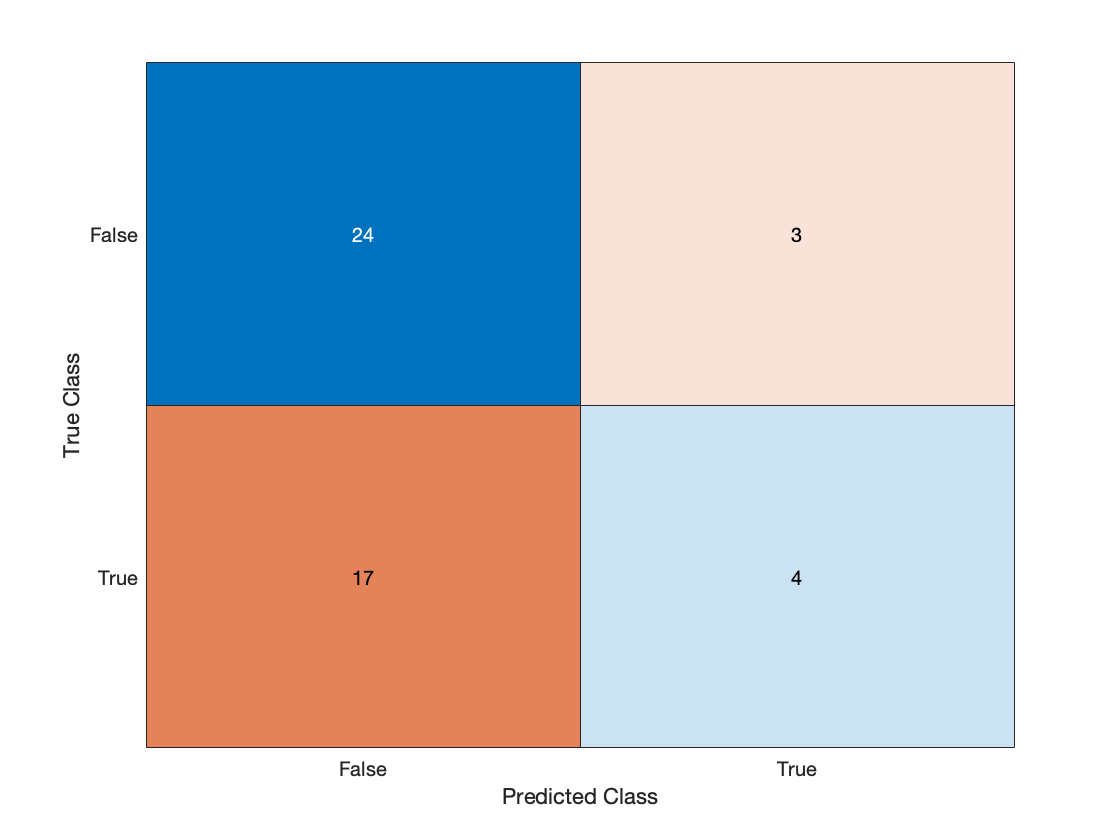



figure('Name','Confusion Chart');
cm =confusionchart(YTest,YPred);



TN = cm.NormalizedValues(1,1);
TP= cm.NormalizedValues(2,2);
FP =cm.NormalizedValues(1,2);
FN =cm.NormalizedValues(2,1);
Total = TN +TP+FP+FN;
accuracy =(TP+TN)/Total

accuracy = 0.5833



TPR = TP/(FN+TP);
TNR = TN/(TN+FP);
FPR = FP/(TN+FP);
Presion = TP/(TP+FP)

Presion = 0.5714

Recall = TP/(TP+FN)

Recall = 0.1905

f1_pres = 1/Presion;
f1_recall = 1/Recall;
F1 = 2*(1/(f1_pres + f1_recall))

F1 = 0.2857

%https://towardsdatascience.com/the-3-most-important-composite-classification-metrics-b1f2d886dc7b
balanced_accuracy = (TPR+ TNR)/2

balanced_accuracy = 0.5397

actual = YTest =='True';
pred = YPred =='True';
[X,Y,T,AUC,OPTROCPT] = perfcurve(double(actual),double(pred),1);
AUC

AUC = 0.5397


% plot(X,Y)
num = TP*TN-FP*FN;
denom = (TP+FP)*(TP+FN)*(TN+FP)*(TN+FN);
MCC = num / sqrt(denom)

MCC = 0.1116